# Parse .hmod Files

Suppose you have KS_JEDC10.hmod in the working directory. Call in MATLAB

clear_hans
hans KS_JEDC10

Parsing...ok!
Compiling dpopt_vfi
Building with 'MinGW64 Compiler (C++)'.
MEX completed successfully.


ans = struct with fields:
               parameters: {'beta'  'r'  'w'}
                var_shock: 'e'
                var_state: 'a'
              var_pre_vfi: 'budget'
               var_policy: 'ap'
                  var_aux: 'c'
                  var_agg: 'K'
            var_agg_shock: 'Z'
           var_agg_params: {'alpha'  'delta'  'L'}
           var_agg_assign: {'r'  'w'}
    var_agg_in_ind_params: {'r'  'w'}
            var_ind_in_eq: 'ap'

As shown, HANS parases the hmod file, compiles the mex files, and returns a structure that describes the model.

clear_hans in the first line clears any cached files generated before.

# Solve the Stationary Equilibrium

Call the generated code solve_ss to solve the stationary equilibrium

tic;
ss_rslt = solve_ss;

Evaluating at var_agg: 43, 
VFI converged (metric_v) 0.00663442, (metric_pol) 0 in 489 iterations
Range of a: 0, 18.9484
Equilbirium residual: 32.0071, 

     Iteration    Line Search     Func-count    ||f(x)||^2     fnorm(x)      Norm of Step      Step Size      Algorithm

             0              0              1   1.024452e+03   3.200706e+01
Evaluating at var_agg: 43.0043, 
VFI converged (metric_v) 0.000364795, (metric_pol) 0 in 290 iterations
Range of a: 0, 18.9484
Equilbirium residual: 32.015, 
Evaluating at var_agg: 40.5, 
VFI converged (metric_v) 2.14285e-05, (metric_pol) 0 in 646 iterations
Range of a: 0, 30.8489
Equilbirium residual: 26.1081, 

             1              1              3   6.816343e+02   2.610813e+01   2.500000e+00   1.437515e-01         Newton
Evaluating at var_agg: 39.25, 
VFI converged (metric_v) 1.0435e-06, (metric_pol) 0 in 865 iterations
Range of a: 0, 60.5201
Equilbirium residual: 20.2586, 

             2              1              4   4.104102e+0

fprintf('Time used for solving the stationary equilibrium:\n');toc;

Time used for solving the stationary equilibrium:
Elapsed time is 1.432989 seconds.


ss_rslt

ss_rslt = struct with fields:
                vfi_rslt: [1×1 struct]
                   stats: [1×1 struct]
                 var_agg: [1×1 struct]
                    dist: [2×500 double]
              parameters: [1×1 struct]
          var_agg_params: [1×1 struct]
             shock_trans: [2×2 double]
    shock_invariant_dist: [2×1 double]
                   resid: 5.7108e-06
               exit_flag: 1
               rslt_type: 'ss'
           solver_output: [1×1 struct]
           ind_rslt_dict: [1×1 ArrayKeyMap]

As shown, the function returns a structure that describes the solved stationary equilibrium.

We can inspect the values of equilibrium variables:

ss_rslt.var_agg

ans = struct with fields:
    K: 38.2691
    Z: 1
    r: 0.0099
    w: 2.3769
    Y: 3.7139
    I: 0.9567
    C: 2.7571

We can insepct the stationary distribution

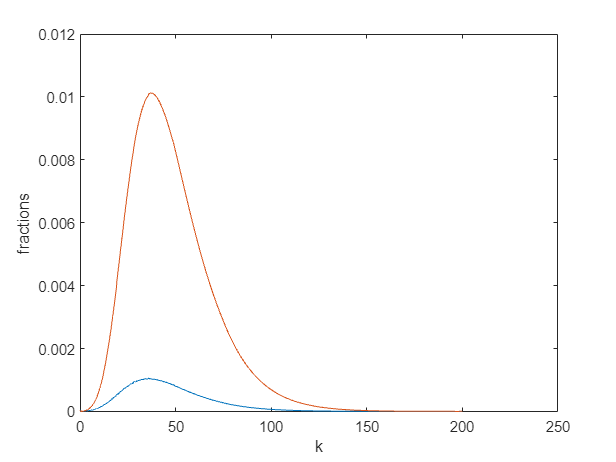

plot(ss_rslt.vfi_rslt.var_state.a, ss_rslt.dist);
xlabel('k');
ylabel('fractions');

and the policy functions

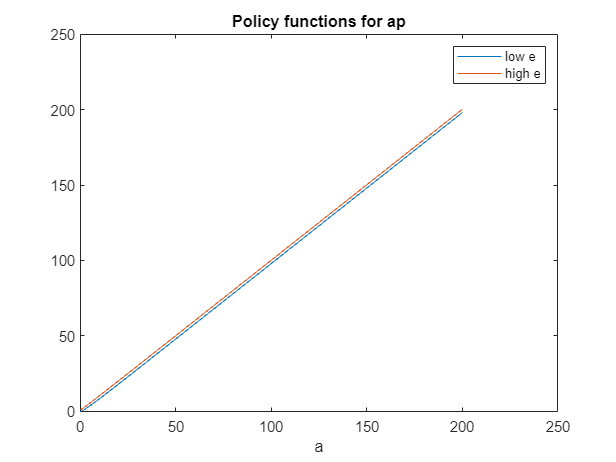

plot(ss_rslt.vfi_rslt.var_state.a, ss_rslt.vfi_rslt.var_policy.ap);
xlabel('a');
title('Policy functions for ap');
legend({'low e','high e'})

# Solve the Transition Path After A Temporay Shock

## Solve the linearized transition path

We first construct the sequence of productivity shock.

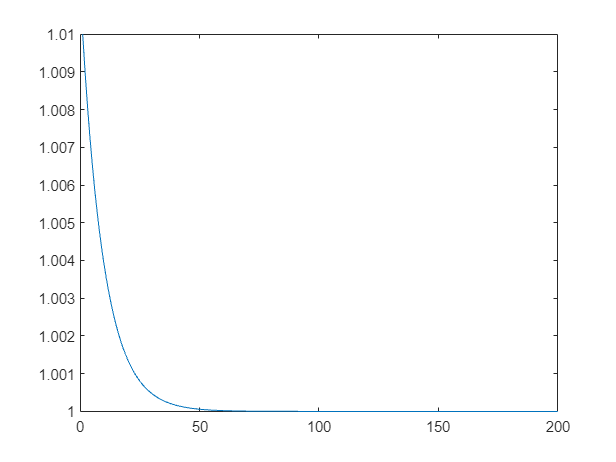

T = 200;
shock_Z = 0.01; rho_Z = 0.9;
Z_t = 1 + shock_Z *rho_Z.^(0:(T-1));
figure;
plot(Z_t)

We then pass the productivity shock and the solved ss_rslt into solve_trans_linear to solve the linearized transition path.

options = struct;
options.T = T;
options.Z_t = Z_t;
tic;
trans_linear_rslt = solve_trans_linear(ss_rslt, options);
fprintf('Time used for solving the linearized transition path:\n');toc;

Time used for solving the linearized transition path:
Elapsed time is 0.725552 seconds.


trans_linear_rslt

trans_linear_rslt = struct with fields:
             var_agg_t: [1×1 struct]
       var_agg_shock_t: [1×1 struct]
      jacs_ind_wrt_agg: {[200×200 double]  [200×200 double]}
    jac_eqs_of_var_agg: [200×200 double]
               irf_ssj: [200×200 double]

We can plot the transition path (note that K is the next period capital).

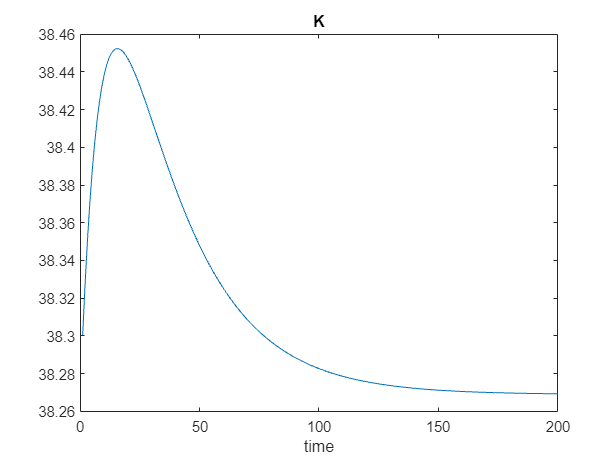

figure;
plot(trans_linear_rslt.var_agg_t.K)
title('K');
xlabel('time');

## Solve the nonlinear transition path

Now we pass the solved ss_rslt to solve_nonlinear_trans(init_ss, final_ss, options) to solve the nonlinear transition path.

Note that we pass ss_rslt as both init_ss and final_ss.

tic;
trans_nonlinear_rslt = solve_trans_nonlinear(ss_rslt, ss_rslt, options);

     Iteration    Line Search     Func-count    ||f(x)||^2     fnorm(x)      Norm of Step      Step Size      Algorithm

             0              0              1   5.800552e-04   2.408433e-02

             1              1              2   6.663947e-10   2.581462e-05   3.095308e-03   1.000000e+00        Broyden


fprintf('Time used for solving the nonlinear transition path:\n');toc;

Time used for solving the nonlinear transition path:
Elapsed time is 1.320027 seconds.


trans_nonlinear_rslt

trans_nonlinear_rslt = struct with fields:
          var_agg_t: [1×1 struct]
    var_agg_shock_t: [1×1 struct]
                  T: 200
           vfi_rslt: [1×1 struct]
        shock_trans: [2×2 double]
           exitflag: 1
             HANS_x: [200×1 double]
          eqs_resid: [200×1 double]
          rslt_type: 'nonlinear_trans'
      solver_output: [1×1 struct]

We compare the solution of the nonlinear transition path and the linear transition path.

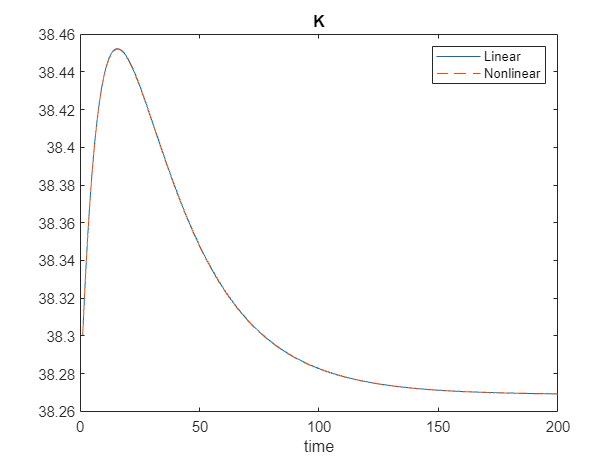

figure;
plot(trans_linear_rslt.var_agg_t.K);
hold on;
plot(trans_nonlinear_rslt.var_agg_t.K, '--');
xlabel('time');
title('K');
legend({'Linear','Nonlinear'});

We can also inspect other defined equilibrium varialbes along the transition path.

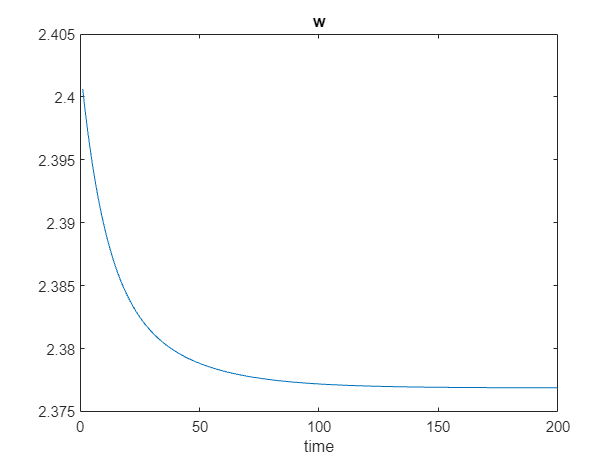

figure;
plot(trans_nonlinear_rslt.var_agg_t.w);
title('w');
xlabel('time');

# Solve the Transition Path After A Permanent Shock

We now consider an unexpected shock that raises Z permanently by 100%.

We first sovle the new stationary equilibrium.

options = struct;
options.Z = 2.0;
ss_rslt_new = solve_ss(options);

Evaluating at var_agg: 43, 
VFI converged (metric_v) 0.0403421, (metric_pol) 0 in 413 iterations
Range of a: 0, 200
Equilbirium residual: -160.841, 

     Iteration    Line Search     Func-count    ||f(x)||^2     fnorm(x)      Norm of Step      Step Size      Algorithm

             0              0              1   2.586975e+04   1.608408e+02
Evaluating at var_agg: 43.0043, 
VFI converged (metric_v) 0.00550782, (metric_pol) 0 in 199 iterations
Range of a: 0, 200
Equilbirium residual: -160.836, 
Evaluating at var_agg: 195.495, 
VFI converged (metric_v) 0.0173235, (metric_pol) 0 in 251 iterations
Range of a: 0, 25.1867
Equilbirium residual: 177.356, 

             1              1              3   3.145508e+04   1.773558e+02   1.524948e+02   1.000000e+00         Newton
Evaluating at var_agg: 119.247, 
VFI converged (metric_v) 0.000418207, (metric_pol) 0 in 593 iterations
Range of a: 0, 95.5869
Equilbirium residual: 75.8555, 

             1              2              4   5.754062e+03  

We then solve the transition path from the initial stationary equilibrium to the new stationary equilibrium.

options = struct;
T = 200;
options.Z_t = 2.0*ones(1,T);  % shock hits at period 1
options.T = T;
tic;
trans_to_new_ss_rslt = solve_trans_nonlinear(ss_rslt, ss_rslt_new, options);

     Iteration    Line Search     Func-count    ||f(x)||^2     fnorm(x)      Norm of Step      Step Size      Algorithm

             0              0              1   5.361269e+05   7.322069e+02

             1              1              2   1.831519e+04   1.353336e+02   2.746381e+02   1.000000e+00        Broyden

             2              1              3   1.928935e+03   4.391964e+01   2.326839e+01   1.000000e+00        Broyden

             3              1              4   1.277507e+00   1.130268e+00   4.819679e+00   1.000000e+00        Broyden

             4              1              5   1.582870e-01   3.978530e-01   5.717419e-01   1.000000e+00        Broyden

             5              1              6   1.003643e-04   1.001820e-02   1.033724e-01   1.000000e+00        Broyden

             6              1              7   1.266697e-08   1.125476e-04   2.258355e-03   1.000000e+00        Broyden

             7              1              8   3.681201e-11   6.067290e-06   

fprintf('Time for solving the nonlinear transition path after a permanent shock:\n');toc;

Time for solving the nonlinear transition path after a permanent shock:
Elapsed time is 2.078643 seconds.


trans_to_new_ss_rslt

trans_to_new_ss_rslt = struct with fields:
          var_agg_t: [1×1 struct]
    var_agg_shock_t: [1×1 struct]
                  T: 200
           vfi_rslt: [1×1 struct]
        shock_trans: [2×2 double]
           exitflag: 1
             HANS_x: [200×1 double]
          eqs_resid: [200×1 double]
          rslt_type: 'nonlinear_trans'
      solver_output: [1×1 struct]

We next inspect the nonlinear transition path.

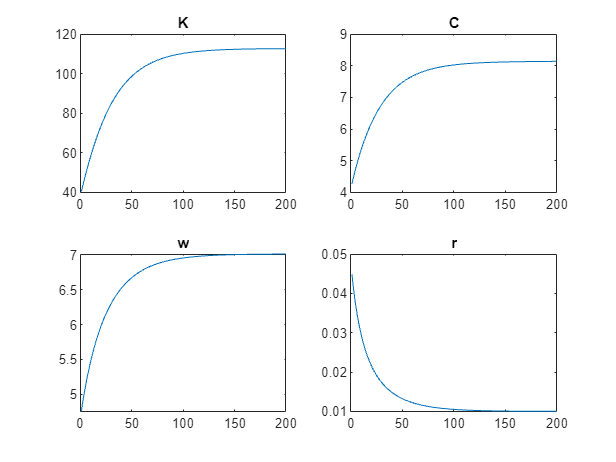

figure;
subplot(2,2,1);
plot(trans_to_new_ss_rslt.var_agg_t.K); title('K');
subplot(2,2,2);
plot(trans_to_new_ss_rslt.var_agg_t.C); title('C');
subplot(2,2,3);
plot(trans_to_new_ss_rslt.var_agg_t.w); title('w');
subplot(2,2,4);
plot(trans_to_new_ss_rslt.var_agg_t.r); title('r');

# Simulate Individual Samples

## Simulate Individual Samples at the Stationary Distribution

We can simulate individual samples at the stationary equilibrium or along the transition path.

Let's start with the stationary equilibrium.

tic;
simu_rslt = simulate_stochastic(ss_rslt);

  period   shock       a      ap       cstate_transition_value_1
    1000   1.899   37.77   37.77   2.752   37.77


fprintf('Time used for simulating individual samples at the stationary equilibrium:\n');toc;

Time used for simulating individual samples at the stationary equilibrium:
Elapsed time is 0.805281 seconds.


simu_rslt

simu_rslt = struct with fields:
                       shock: [10000×1000 double]
                           a: [10000×1000 double]
                          ap: [10000×1000 double]
                           c: [10000×1000 double]
    state_transition_value_1: [10000×1000 double]

As shown, passing ss_rslt to simulate_stochastic returns a panel of simualted individual samples.

Printed information is the mean of variables at the printed period.

By default, it simulates 10,000 samples for 1,000 periods, and starts from random state values drawn from the stationary distribution.

We can overwrite the num_samples and num_periods:

simu_options = struct;
simu_options.num_samples = 2e4;
simu_options.num_periods = 2e3;
tic;
simu_rslt = simulate_stochastic(ss_rslt, simu_options);

  period   shock       a      ap       cstate_transition_value_1
    1000   1.898   37.94   37.94   2.754   37.94
    2000     1.9   37.59   37.59   2.749   37.59


fprintf('Time used for simulating 2e4 individual samples for 2e3 periods at the stationary equilibrium:\n');toc;

Time used for simulating 2e4 individual samples for 2e3 periods at the stationary equilibrium:
Elapsed time is 2.538545 seconds.


We can compare the histogram of simulated individual samples to the one constructed based on the non-stochastic simulation.

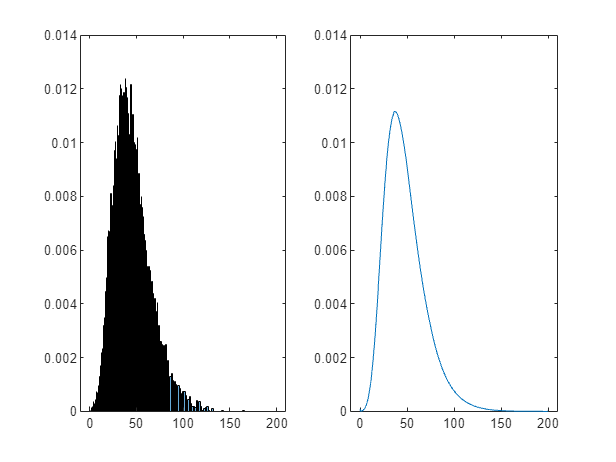

figure; 
subplot(1,2,1);
histogram(simu_rslt.a(:,end),ss_rslt.vfi_rslt.var_state.a,'Normalization','probability');
xlim([-10,210]);ylim([0,0.014]);
subplot(1,2,2);
plot(ss_rslt.vfi_rslt.var_state.a, sum(ss_rslt.dist,1)');
xlim([-10,210]);ylim([0,0.014]);

## Simulate Individual Samples Along the Transition Path

To simulate individual samples along the transition path, we need to specify values of initial state values.

Let's specify them to be drawn from the stationary distribution.

simulate_initials = struct;
% Use the last period of the simulated results at the stationary distirubtion
simulate_initials.shock = simu_rslt.shock(:,end);
simulate_initials.a = simu_rslt.a(:,end);

We now pass the initial values into options, and simulate individual samples along the transition path to the new stationary equilibrium.

simu_options = struct;
simu_options.num_samples = 2e4;  % to be consistent with size of initial values
simu_options.simulate_initials = simulate_initials;
simu_trans_rslt = simulate_stochastic(trans_to_new_ss_rslt, simu_options);

  period   shock       a      ap       cstate_transition_value_1
    0200   1.899   114.4   114.4   8.145   114.4


We then compare the aggregate variables constructed from individual samples and from non-stochastic simulations.

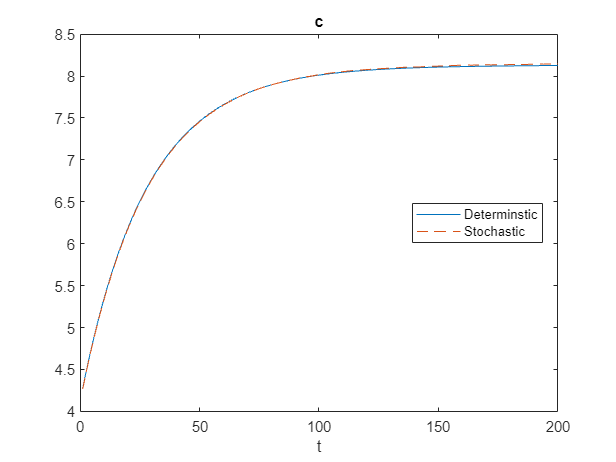

figure;
plot(trans_to_new_ss_rslt.var_agg_t.c,'-');
hold on;
plot(mean(simu_trans_rslt.c),'--');
legend({'Determinstic', 'Stochastic'},'Location','Best');
title('c');
xlabel('t');